modulePath = 'C:\Users\Asus\Studia\Indywidualny Program Studiów\IPS - Projekt\dane - semestr 5\MATLAB_project\python_modules';
insert(py.sys.path, int32(0), modulePath);
load('C:\Users\Asus\Studia\Indywidualny Program Studiów\IPS - Projekt\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat')

function results_py = model_hybrid(y_train, y_test, step_length,  ma_window, season_period)
    py_model = py.importlib.import_module("model_hybrid");
    results_py = py_model.model_hybrid(...
        y_train, ... 
        y_test, ...
        step_length, ...
        pyargs('ma_window', ma_window, 'season_period', season_period, 'verbose', true) ...
    ).double';
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

train_data = ab_diff_train_norm;
test_data = ab_diff_test_norm;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

test_length = dlugosc_testu_oryginalna;
step_length = 1;

% Przewidywania A1 - model hybrydowy
prediction = model_hybrid(train_data, test_data(1:test_length), step_length, 32, 96*7);

Step: 1 / 2880
Step: 2 / 2880
Step: 3 / 2880
Step: 4 / 2880
Step: 5 / 2880
Step: 6 / 2880
Step: 7 / 2880
Step: 8 / 2880
Step: 9 / 2880
Step: 10 / 2880
Step: 11 / 2880
Step: 12 / 2880
Step: 13 / 2880
Step: 14 / 2880
Step: 15 / 2880
Step: 16 / 2880
Step: 17 / 2880
Step: 18 / 2880
Step: 19 / 2880
Step: 20 / 2880
Step: 21 / 2880
Step: 22 / 2880
Step: 23 / 2880
Step: 24 / 2880
Step: 25 / 2880
Step: 26 / 2880
Step: 27 / 2880
Step: 28 / 2880
Step: 29 / 2880
Step: 30 / 2880
Step: 31 / 2880
Step: 32 / 2880
Step: 33 / 2880
Step: 34 / 2880
Step: 35 / 2880
Step: 36 / 2880
Step: 37 / 2880
Step: 38 / 2880
Step: 39 / 2880
Step: 40 / 2880
Step: 41 / 2880
Step: 42 / 2880
Step: 43 / 2880
Step: 44 / 2880
Step: 45 / 2880
Step: 46 / 2880
Step: 47 / 2880
Step: 48 / 2880
Step: 49 / 2880
Step: 50 / 2880
Step: 51 / 2880
Step: 52 / 2880
Step: 53 / 2880
Step: 54 / 2880
Step: 55 / 2880
Step: 56 / 2880
Step: 57 / 2880
Step: 58 / 2880
Step: 59 / 2880
Step: 60 / 2880
Step: 61 / 2880
Step: 62 / 2880
Step: 63 / 2880
S

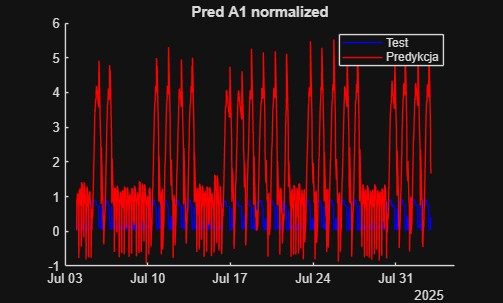

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:test_length), test_data(1:test_length), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:test_length), prediction, 'Color','red','DisplayName','Predykcja');
title('Pred A1 normalized');
legend;

y_test = test_data(1:length(prediction))';

mae_score = mae(y_test, prediction)

mae_score = 1.6226

mape_score = mape(y_test, prediction)

mape_score = 160.7799

rmse_score = rmse(y_test, prediction)

rmse_score = 2.0512

r2_classic = R2_classic(y_test, prediction)

r2_classic = -34.1048

r2_alt = R2_alt(y_test, prediction)

r2_alt = 34.9640

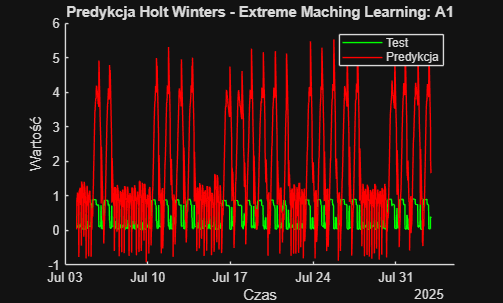


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(prediction)), ab_diff_test_norm(1:length(prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(prediction)), prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters - Extreme Maching Learning: A1")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   prediction(1:dlugosc_testu_oryginalna)', ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'}');

writetable(T_z_czasem, "pred_ab_HYBRYDA_" + num2str(step_length) + "_month.xlsx");